# Text Customizations

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

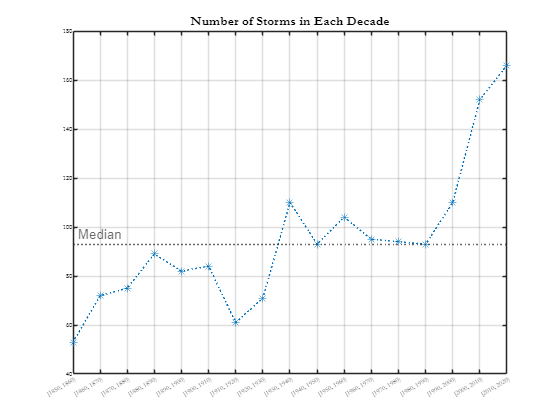

decades = [ "[1850, 1860)";
            "[1860, 1870)";
            "[1870, 1880)";
            "[1880, 1890)";
            "[1890, 1900)";
            "[1900, 1910)";
            "[1910, 1920)";
            "[1920, 1930)";
            "[1930, 1940)";
            "[1940, 1950)";
            "[1950, 1960)";
            "[1960, 1970)";
            "[1970, 1980)";
            "[1980, 1990)";
            "[1990, 2000)";
            "[2000, 2010)";
            "[2010, 2020)"];
numEvents = [53; 72; 75; 89; 82; 84; 61; 71; 110; 93; 104; 95; 94; 93; 110; 152];
the2010s = 166;
p = plot(numEvents);
p.LineStyle = ":";
p.Marker = "*";
p.YData(end+1) = the2010s;
med = median(p.YData);
y = yline(med, ":", "Median");
y.LabelHorizontalAlignment = "left";
grid on
title("Number of Storms in Each Decade")
ax = gca;
ax.XTick = 1:length(decades);
ax.XTickLabels = decades;
ax.FontName = "Garamond";
ax.FontSize = ax.FontSize/2;
ax.TitleFontSizeMultiplier = 2;
ax.XLimitMethod = "tight";

## Task 1

Properties of individual axes are found in the `XAxis` and `YAxis` objects stored in an axes object.

`axesHandle.XAxis`

`axesHandle.YAxis`

yAx = ax.YAxis

yAx =   NumericRuler with properties:

             Limits: [40 180]
              Scale: 'linear'
           Exponent: 0
         TickValues: [40 60 80 100 120 140 160 180]
    TickLabelFormat: '%g'

  Show all properties


## Task 2

You can extract properties of a single axis with dot notation. For instance, you can extract the x-axis limits from either a handle to the x-axis or by using dot notation twice with the axes handle.

This code:

`xHandle` `=` `axesHandle.XAxis`

`xHandle.Limits`

does the same thing as:

`axesHandle.XAxis.Limits`

yFW = yAx.FontWeight

yFW = 'normal'

## Task 3

Use dot notation to modify text properties as you did for axes properties.

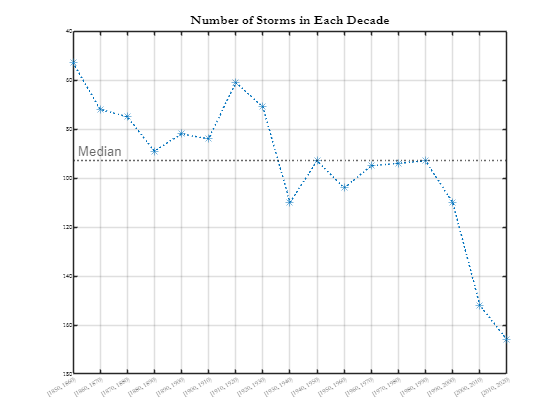

ax =   Axes (Number of Storms in Each Decade) with properties:

             XLim: [1 17]
             YLim: [40 180]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.YAxis.Direction = "reverse"